# Feedback Controls Course Project

Spring 2026

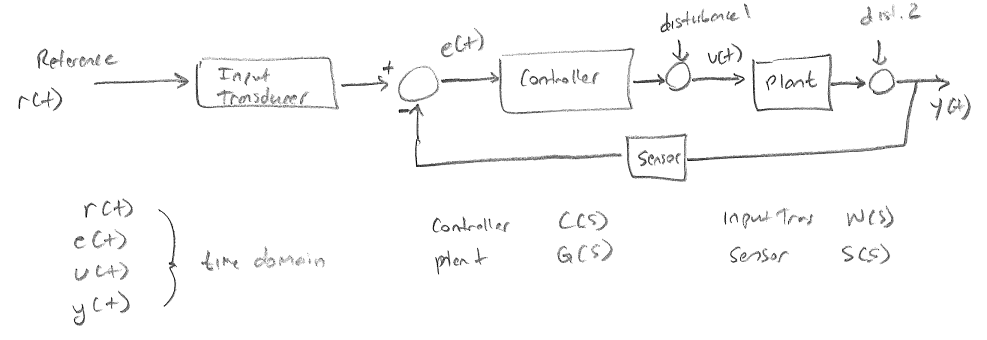

## Welcome!  

The course project is an exciting time to take the material learned and applied in this course and use it on a project of your choice!  Before getting into the excitement of the project, let's cover the paperwork side of things.  From your careful analysis of ELC, you've noticed that overall the final course project is worth **38%** of the course grade.  So, to keep you on track to do well, there are 3 main checkpoints and 1 demonstration day.  See the course schedule and ELC for the due dates for each.  

The burning question... If you are in the 4220 section, you can work in pairs, *or* choose to work alone.  If you are in the 6220 section you must work alone.  The next paperwork issue, is that there are tiers to this report.  Choose to work to what you'd like!  Let's abbreviate "feedback control system" with FBC.  

### Minimum to be considered for a 65%

- Your FBC meets all the system constraints and document expectations (coming later...).

- Your FBC has a working Livescript file that calls a working Simulink simulation.

- In your Simulink simulation you have a Simscape simulation matching your plant.  

- The Livescript uses data from the Simulink Simulation to make plots and figures.  

### Minimum to be considered for a 75%

- You have all of the above AND you have linearized the system about an operating point.  In your code you can change where this operating point is.  This also implies you have derived the mathematics associated with your plant.  

### Minimum to be considered for an 85%

- You have all of the above AND you have implemented a *working* FBC on pre-existing hardware.  

### Minimum to be considered for a 100%

- You have all of the 75% tier AND you have implemented a *working* *FBC on **raw** hardware *you have made during the duration of this class*.  This excludes Capstone projects and other projects where the majority of the work has been completed or funded. Those would fall in the 85% tier.  

**WARNINGS**

- There's a lot of great resources out there!  You must cite the source.  This includes any 3D printing files or anything else used.  

- Copy and pasting [https://github.com/MathWorks-Teaching-Resources/Virtual-Controls-Laboratory](https://github.com/MathWorks-Teaching-Resources/Virtual-Controls-Laboratory) from here or other Mathworks will move you to the 65% tier.  The only permissible copying is Simscape files.  

## Checkpoint 1: Magnetic Levitator

#### Background

Insert a motivational photograph of your desired FBC.  

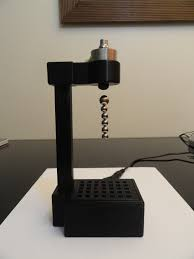

## **Write a paragraph description describing your desired FBC. **

   The magnetic levitator is a closed-loop feedback control system designed to suspend a permanent magnet at a fixed position beneath an electromagnet. The electromagnet is constructed by wrapping copper wire around a cylindrical ferromagnetic core, forming an inductive coil. When current flows through the coil, a magnetic field is generated, producing an attractive force on the magnet. The microcontroller regulates the strength of this magnetic field by controlling the average current through the coil using pulse width modulation (PWM). A Hall-effect sensor positioned at the bottom of the electromagnetic coils measures the local magnetic flux density. Because the magnetic field produced by the permanent magnet varies with distance, the Hall sensor output changes as the magnet moves relative to the sensor. This measurement is fed back into the controller, which adjusts the PWM duty cycle to increase or decrease the coil current, thereby regulating the magnetic force acting on the magnet and maintaining the desired levitation height. 

## **Write a paragraph on the history of your FBC.  Tell the story from when it was first invented/studied to modern day.  Insert photos or links to keep the reader interested.  It's a paragraph, not a chapter. **

    The concept of magnetic levitation (maglev) was first conceived in the early 20th century by Robert Goddard and Emile Bachelet, who first proposed the concept of frictionless travel using electromagnetic repulsion. By 1912, Bachelet had successfully demonstrated a model train that utilized AC solenoids for propulsion, though the technology remained largely theoretical for decades. In the mid 20th century, efforts finally began to develop a high-speed rail system using this technology. In 1966, James Powell and Gordon Danby of Brookhaven National Laboratory proposed the use of superconducting magnets for levitation. Commercial implementation finally took root in the late 20th and early 21st centuries. The first commercial low-speed maglev opened in Birmingham, England, in 1984, followed by Berlin's automated M-Bahn in 1989. While these early European lines were eventually decommissioned, China successfully launched the Shanghai Maglev in 2004, which remains the world’s only high-speed commercial line, reaching speeds of up to 268 mph. Modern development is now led by Japan’s SCMAGLEV system, which set a world speed record of 374 mph in 2015. Even though development has slowed on practically applying maglev for transportation needs, the technology is proven to be a viable alternative to conventional rail and air travel.

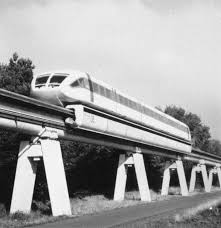

Figure 1.

## **Write a paragraph on a literature study of existing projects similar to yours. Include links and photos as appropriate.  **

    When searching on the internet, we found that some were able to build a variation of our project, with some variations on the application or planned implementation. The first study we found was a magnetic train rail system, that used normal magnets to levitate a wooden block that could be moved on a rail system. This project was not directly applicable to our project, but the concept of using magnets to levitate an object at a constant distance is a principle that we will use.

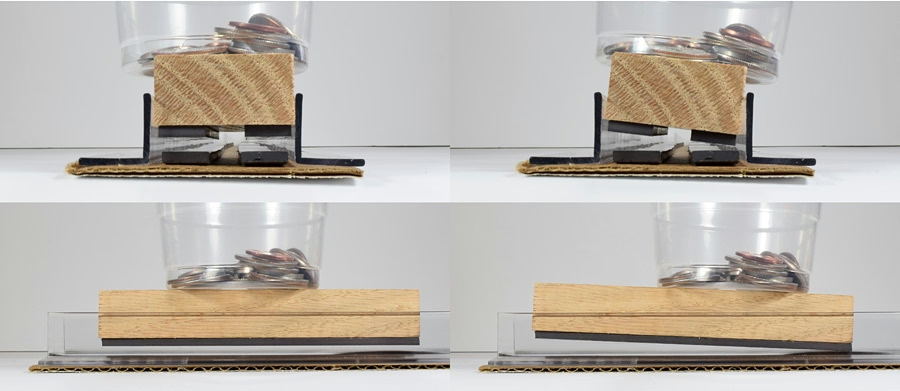

Figure 2.

    Another project that we found was a levitating light project, that is much more applicable to what we are doing. However, instead of using a magnet as a load, the creator fabricated their own magnet using a coil of wire, rather than a permanent magnet. As a result, there is additional circuitry that is needed to wirelessly transfer power from the electromagnet to the light magnet, which we will not be using (we are using a permanent magnet).

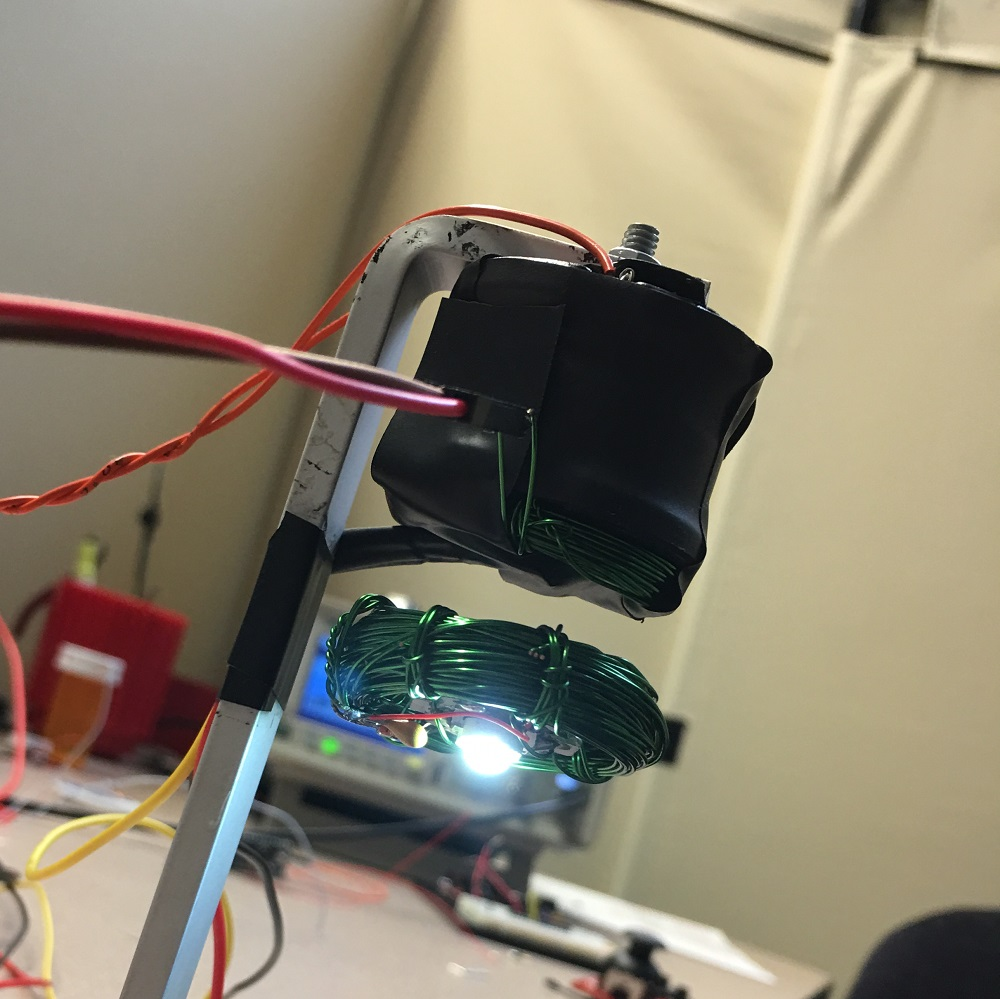

Figure 3.

Train Project: [*https://www.sciencebuddies.org/science-fair-projects/project-ideas/Phys_p093/physics/maglev-train-weight*](https://www.sciencebuddies.org/science-fair-projects/project-ideas/Phys_p093/physics/maglev-train-weight)

*Levitating Light:** https://github.com/awende/Levitating_Light/tree/master*

## ***Give a mathematical description of your system.  ***$\dot{x} =f\left(x\right)$

- **Be sure to use actual equation formatting.  **

- **Be sure to define all parameters.  Be sure to define all units.  **

- **Include any plots or diagrams necessary to support the underlying dynamics.  **

- **Include references of works you are using.  **

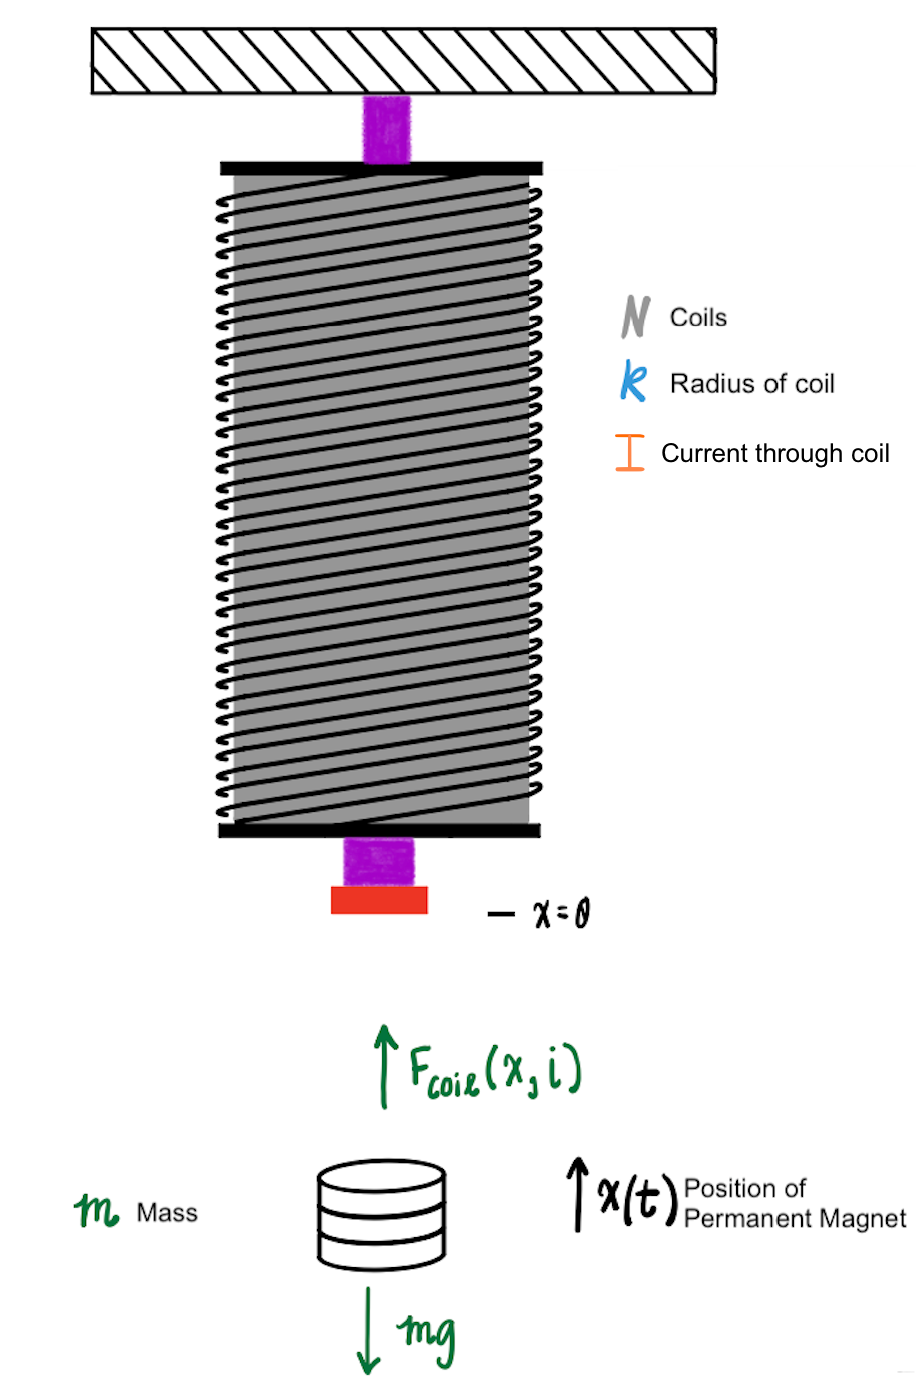

Figure 4. 

    The above image gives a baseline model of the magnetic levitation system. The inductor will act as an electromagnet that produces a magnetic field that attracts the permanent magnet and causes it to levitate. Variables are defined according to the coil: $N$number of coils in the inductor, $R$ radius of the coil loop (m), and $I$ current through the coils (A), which is the input of the feedback control system. The permanent magnet has a mass $m$ (kg) and an output variable $x$, which is the position relative to the base of the inductor coils (m). Let us begin with the fundamental equation of physics: $F=\textrm{ma}\ldotp$ For simplicity, for the duration of the final report, *coils* will be used to describe the electromagnet inductor and *magnet* will be used to describe the levitating permanent magnet. $m\ddot{x} =F_{\textrm{coils}} \left(x,i\right)-\textrm{mg}$ where $F_{\textrm{coils}} \left(x,i\right)$ is the magnetic force of the coils attracting the magnet, not yet defined mathematically. There is also a force of gravity that opposes the upwards movement of the magnet. Finally, at this stage in modeling, any dampening effects or disturbances will be ignored. 

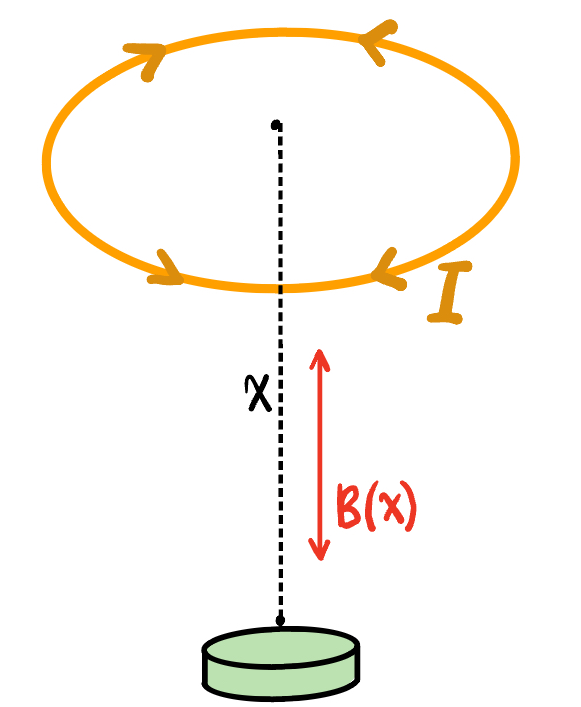

Figure 2. Biot-Savart Law of Single Loop

    The electromagnetic phenomena must be defined to properly define this second order non linear system. According to the Biot-Savart Law, for a circular loop of radius $R$ carrying current $I$, the magnetic field strength at a distance $x$ from the center along the axis is $B\left(x,I\right)=\frac{\mu_0 {\textrm{IR}}^2 }{2{\left(x^2 +R^2 \right)}^{\frac{3}{2}} }$, where $B\left(x\right)\;$is the magnetic flux density (T) as a function of position from the center, $\mu_0 \;$is the permeability of free space (H/m), and $N,I,x,R$ have been previously defined. In the orientation of our magnetic levitator and ignoring any inconsistencies of physical orientation, we can define the magnetic field as pointing directly axialy and perpendicular to the coil loop, according to the Right Hand Rule. This magnetic field orientation is displayed in the figure above. Because magnetic fields obey the principle of superposition, the magnetic field produced by an electromagnet consisting of $N$ identical circular coils carrying current $I$ can be approximated as the sum of the fields produced by each loop individually, resulting in the axial magnetic field expression: [1]

$B\left(x,I\right)=\frac{N\mu_0 {\textrm{IR}}^2 }{2{\left(x^2 +R^2 \right)}^{\frac{3}{2}} }$. 

    At this point, the magnetic force on the permanent magnet, $F_{\textrm{coils}} \left(x,i\right)$ is still not fully defined. The force acting on a magnetic dipole in a non-uniform magnetic field can be expressed using the dipole force relation: $\vec{F} =\nabla \left(\vec{m} \cdot \vec{B} \right)$where $\vec{F}$is the magnetic force vector (N), $\vec{m}$ is the magnetic dipole moment vector of the permanent magnet (${\textrm{Am}}^2$), and $\vec{B}$ is the magnetic flux density vector at the magnetic location (T). [2] The gradient operator tells that the force on a magnetic object in a non-uniform field is proportional to the spatial gradient (the rate of change) of that field. Furthermore this gradient is equal to the vector of partial derivatives of a scalar field. Thus, $\nabla B=\left\lbrack \begin{array}{c}
\frac{\partial f}{\partial x}\\
\frac{\partial f}{\partial y}\\
\frac{\partial f}{\partial y}
\end{array}\right\rbrack$. [3] In the magnetic levitation configuration shown in Figure 1, the permanent magnet moves only along the central axis of the coil. Due to the cylindrical symmetry of the circular coil, the magnetic field has no horizontal components and only varies along the axial direction. Consequently, the gradient reduces to a single derivative along the axis of motion. The dipole force on the magnet expression is therefore simplified to $F_{\textrm{coils}} \left(x,i\right)=m_d \frac{\textrm{dB}}{\textrm{dx}}$ where $m_d$ is the magnitude of the magnetic dipole moment of the permanent magnet (${\textrm{Am}}^2$) and $\frac{\textrm{dB}}{\textrm{dx}}$ is the spatial gradient of the magnetic field along the coil axis (T/m). 

    The derivative of $B\left(x\right)$ must be found as such:


$$\frac{\textrm{dB}}{\textrm{dx}}=\frac{d}{\textrm{dx}}\left\lbrack \frac{N\mu_0 {\textrm{IR}}^2 }{2}\cdot {\left(x^2 -R^2 \right)}^{\frac{-3}{2}} \right\rbrack =-\frac{3N\mu_0 {\textrm{IR}}^2 x}{2{\left(x^2 +R^2 \right)}^{\frac{5}{2}} }$$


    Therefore, the magnetic force produced by the coil acting on the magnet can be written as

$F_{\textrm{coils}} \left(x,I\right)=\frac{3\mu_0 N{\textrm{IR}}^2 m_d x}{2{\left(x^2 +R^2 \right)}^{\frac{5}{2}} }\;$. 

where the sign will depend on the defined coordinate convention. Finally, substituting this force into Newtown's second law as previosly explained provides the basic nonlinear second-order model of the levitation system: 


$$m\ddot{x} =\frac{3\mu_0 N{\textrm{IR}}^2 m_d x}{2{\left(x^2 +R^2 \right)}^{\frac{5}{2}} }-\textrm{mg}$$
 

## Give discussion on a nominal model vs calibration model.  

    In the context of feedback control systems, a nominal model and a calibration model boil down to a theoretical expectation of how a system will behave, and the physical reality of how the model behaves. A nominal model is the baseline mathematical representation of a system built purely from first principles (physics, kinematics, or circuit theory) and ideal assumptions. It often ignores messy, nonlinear real-world factors to keep the math manageable by assuming factors such as zero friction, perfectly rigid materials, or perfectly uniform magnetic fields. The model above initially ignores any air damping, magnetic field interactions with the coil geometry, Hall sensor dynamics, eddy currents, and more. 

    A calibration model is obtained after experimental data from the physical system is used to adjust the parameters of the nominal model so that the model more accurately reflects the actual system behavior. This is obtained after taking the nominal model and mathematically tuning its parameters so that its outputs match the actual data collected from the physical hardware. Calibration helps capture un-modeled dynamics and hardware imperfections, so if the physical system responds slower than the nominal math predicts, the calibration process adjusts factors like damping or inertia to bridge that gap. By fitting the model parameters to measured data, the calibrated model produces predictions that better match the real system response and can therefore be used more reliably for controller design and performance analysis.

## Using your mathematical description, describe the "ails" of your open-loop system. 

- Include any plots, diagrams, etc to support your discussion. 

- The best feedback controller is no feedback controller as you have a system that behaves exactly how you want.  Explain the dynamics of your system and what (if any) structural changes you can make to the plant to get better open-loop performance. Without applying feedback control.  

    Using the nonlinear dynamic model derived earlier, $m\ddot{x} =\frac{3\mu_0 N{\textrm{IR}}^2 m_d x}{2{\left(x^2 +R^2 \right)}^{\frac{5}{2}} }-\textrm{mg}$, the motion of the permanent magnet depends on the difference between the magnetic force generated by the electromagnet and gravity. The magnetic force is a nonlinear function of coil current $I$ and magnet position $x$. 

    Considering the system as open loop, then the current $I$ would be fixed. Equilibrium or a steady state condition would be when there is no acceleration and the net force on the magnet is zero, $\frac{3\mu_0 N{\textrm{IR}}^2 m_d x_e }{2{\left(x^2 +R^2 \right)}^{\frac{5}{2}} }=\textrm{mg}$ where $x_e$ is the equilibrium levitation height. 

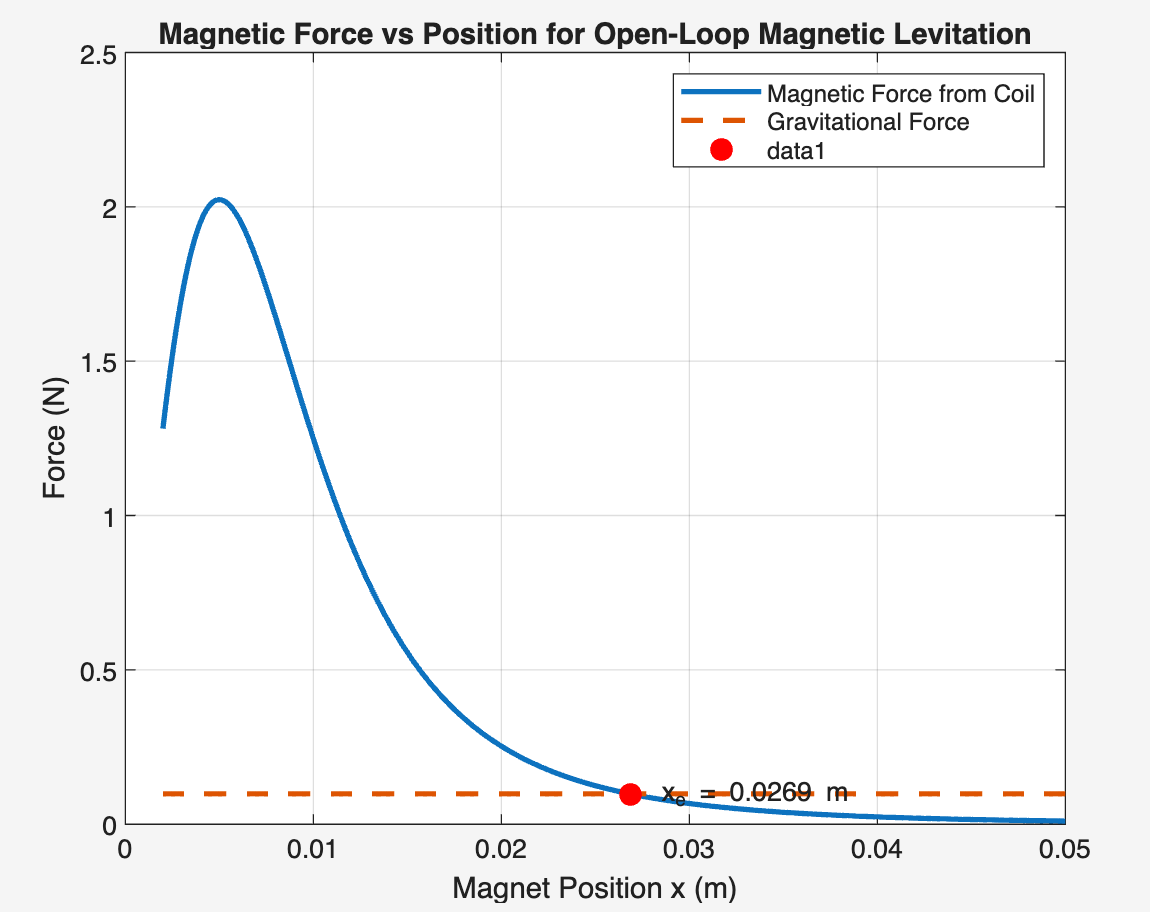

Figure X. Magnetic Force Vs. Position (N=500, I=1.5, R=.01,md=0.5,m=.01,g=9.81)

    Figure X shows the magnetic force produced by the coil as a function of magnet position for a fixed open-loop current, with the constant gravitational force. The intersection of these two curves represents the theoretical equilibrium position $x_e$, where the upward magnetic force exactly balances the downward gravitational force. However, this equilibrium is unstable. For positions slightly greater than $x_e$, the magnetic force becomes smaller than gravity, causing the magnet to fall downward. For positions less than $x_e$ the magnetic force exceeds gravity, causing the magnet to accelerate upward. Therefore, although the open-loop system has a theoretical equilibrium point, it cannot maintain levitation without feedback control.The unstable behavior is as follows: 

- If the magnet moves slightly upward, the magnetic force increases, causes the magnet to accelerate upwards and collide with the coils. The converse exists in the opposite direction when the magnet moves slightly downwards and will fall. 

   Furthermore, the force term $F_{\textrm{coils}} \left(x,i\right)=\frac{3\mu_0 N{\textrm{IR}}^2 m_d x}{2{\left(x^2 +R^2 \right)}^{\frac{5}{2}} }\;$is nonlinear with respect to position as small changes in distance cause large changes in force, making the open-loop system unstable. 

### Improvements

    There exist some physical modifications to the system in order to force the plant into better open-loop performance. 

- Increasing the coil radius $R$ or number of turns $N$: This will increase the achievable magnetic force and may allow the magnet to levitate at further distances with less effect to the change in position. This will reduce sensitivity to position disturbances. 

- Improve mechanical alignment: Ensure that the magnet remains constrained to moving only along the central axis to ensure the assumptions of ignoring $y,z$ magnetic field orientations do not affect the model. 

- Optimize Coil Geometry: The geometry of the electromagnet affects the magnetic field distribution. Designing the coil with a uniform radius and proper material will help produce a smoother and more predictable magnetic field gradient, matching the assumptions of the math model. 

- Limiting Eddy Currents: Eddy currents are circulating currents in nearby conductive materials that oppose the original magnetic field. These can be introduced in nearby conductive components such as the electromagnet core, the mounting structure, or other metallic supports. These effects can be reduced by laminating the magnet cores, or using insulalting layers between conductive materials. 

#### Simulation

% Use MATLAB to define parameters and equations.  NOTE at this point many parameters may not be fully known if you are going for higher grades.  This is ok, for now choose an initial guess.  

m = 0.01;         % Mass (kg) (estimated)
g = 9.81;         % Gravity (m/s^2)
R = 2;            % Coil Resistance (Ohms)
L = 0.25;         % Coil Inductance (H)
N = 500;          % Number of turns
R_coil = 0.01;    % Coil radius (m)
m_mag = 0.5;      % Magnetic moment (A*m^2)
mu0 = 4*pi*1e-7;  % Permeability of free space

% Lumped force constant
K_force = (3 * mu0 * N * m_mag * R_coil^2) / 2;

% Initial starting height (mm) (estimated)
x0 = 0.0254;  % starts resting on the ground

Then create a Simulink simulation of your model that is called from those parameters.  

% insert a call to Simulink...
model_name = 'MagneticLevitator';
out = sim(model_name)

out =   Simulink.SimulationOutput:

                 simout: [1x1 timeseries] 
         simout_current: [1x1 timeseries] 
           simout_force: [1x1 timeseries] 
             simout_vel: [1x1 timeseries] 
                   tout: [199x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Use a SIMOUT block to take your results back here and create visually appealing plots.  

- Show key results from the open-loop simulation

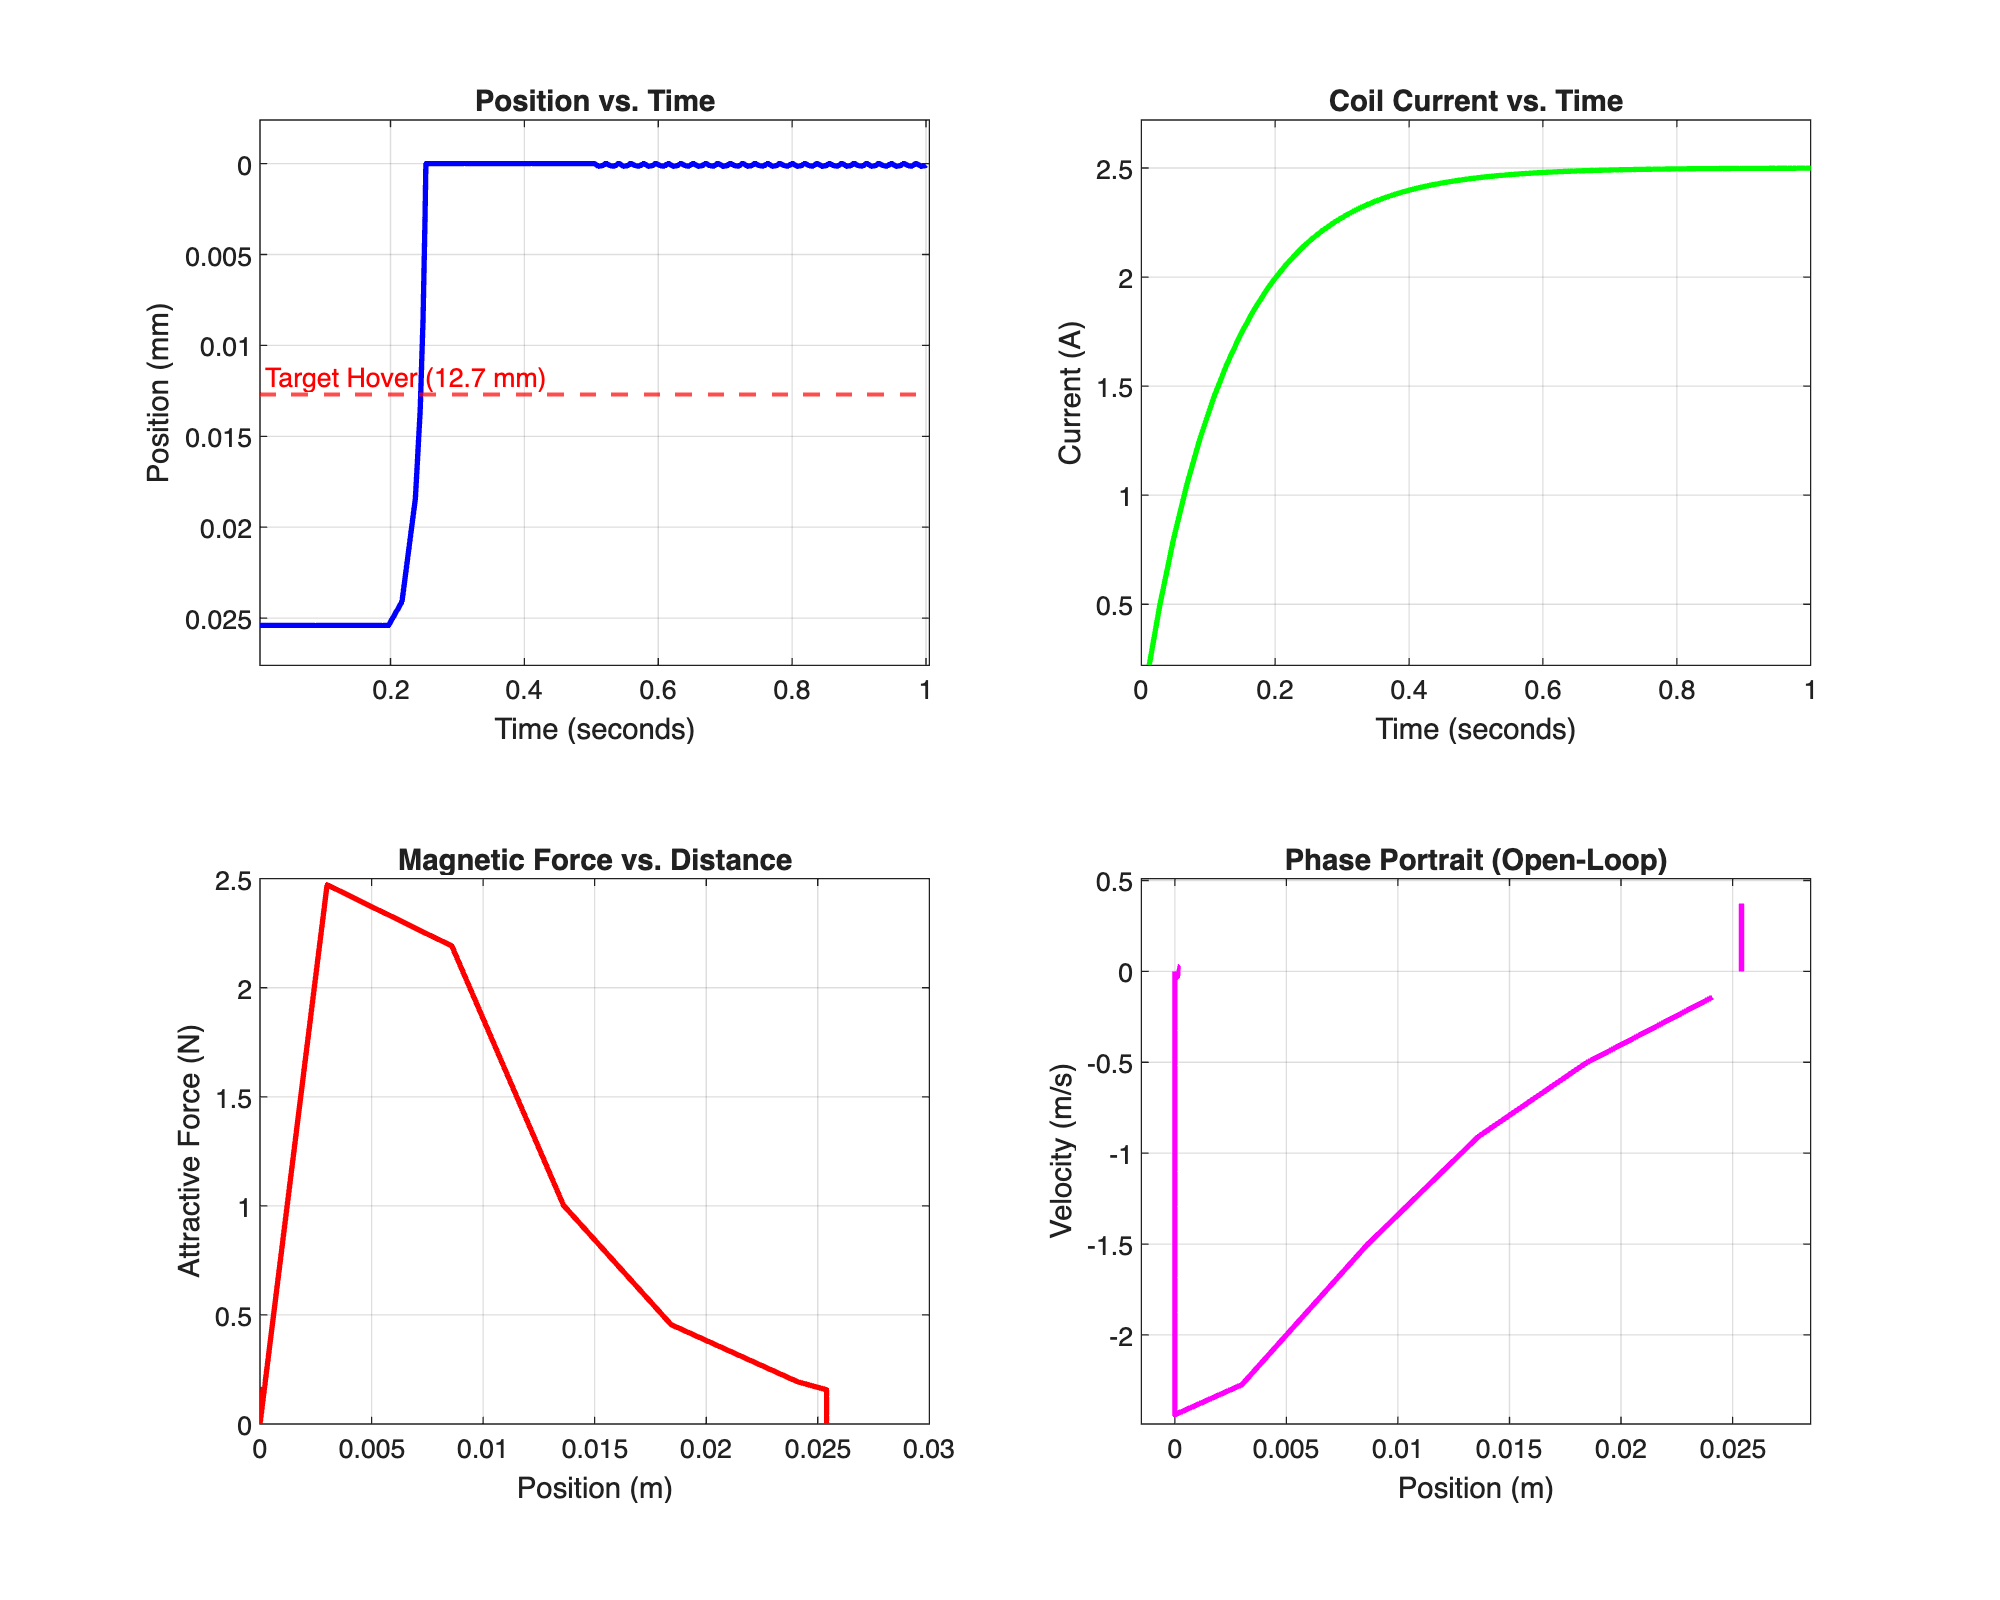

% Create plots
time = out.simout.Time;
pos = out.simout.Data;
force = out.simout_force.Data;
current = out.simout_current.Data;
vel = out.simout_vel.Data;

figure('Position', [100, 100, 1000, 800]);

subplot(2,2,1);
plot(time, pos, 'b-', 'LineWidth', 2); % Position in mm
hold on;
yline(0.0127, 'r--', 'Target Hover (12.7 mm)', 'LineWidth', 1.5, 'LabelHorizontalAlignment', 'left');
hold off;
grid on;
title('Position vs. Time');
xlabel('Time (seconds)');
ylabel('Position (mm)');
set(gca, 'YDir', 'reverse');

subplot(2,2,2);
plot(time, current, 'g-', 'LineWidth', 2);
grid on;
title('Coil Current vs. Time');
xlabel('Time (seconds)');
ylabel('Current (A)');

subplot(2,2,3);
plot(pos, force, 'r-', 'LineWidth', 2); 
grid on;
title('Magnetic Force vs. Distance');
xlabel('Position (m)');
ylabel('Attractive Force (N)');

subplot(2,2,4);
plot(pos, vel, 'm-', 'LineWidth', 2);
grid on;
title('Phase Portrait (Open-Loop)');
xlabel('Position (m)');
ylabel('Velocity (m/s)');

subplot(2,2,1)
xlim([0.005 1.005])
ylim([-0.0024 0.0276])
subplot(2,2,2)
xlim([0.000 1.000])
ylim([0.22 2.72])
subplot(2,2,4)
xlim([-0.0015 0.0285])
ylim([-2.49 0.51])

## Include a paragraph of analysis on the open-loop system.  

    As shown from the plots above, the system is inherently unstable in an open loop configuration when using a constant 5V input to the system. The **position versus time** plot shows that the magnet initially resting on the base rapidly accelerates toward the electromagnet once enough current is applied in the coil. The system is not able to keep the magnet suspended to the target height of 12.7mm, and the magnet is attracted to the coil and sticks to it, stuck at x = 0. This is due to the nonlinear dependance of force on distance. The **magnetic force versus distance plot** further illustrates the strong nonlinear relationship between force and position, showing that small changes in distance produce large changes in magnetic force.  Since the force of the coil is determined by the position of the magnet and the current through the coil, both must be controlled via feedback control in order to acheive the levitation effect. 

## Checkpoint 2: Sensors, Actuators, and Signals

Now we start building the Golden Model around your desired plant. 

### Sensors

From a theoretical perspective, describe what measurements need to be made to your system.  

From a practical perspective, describe how you are going to make the measurements.  If you are going for a 75% you still need to include information about a hypothetical sensor.  

Include links to datasheets, figures, photos, etc.  

*Include how you are modeling and powering the sensor.  Include your sample rate from the sensor.  Include physical limits.  *

% Code! 

### Actuators

From a theoretical perspective, describe what measurements need to be made to your system.  

From a practical perspective, describe how the actuator is going to apply input to the system.  If you are going for a 75% you still need to include information about a hypothetical sensor.  

Include links to datasheets, figures, photos, etc.  

*Include how you are modeling and powering the actuator.  What physical limitations are there on the actuator?  Saturation, input rates?  Include all physical limits.  *

% Code! 

### Signals

Include any information about disturbances in your system.  

Include a characterization of noise in your system.  

Include any information about gains needed to balance units (i.e. 0-12V vs 0-100%).  

% Code! 

### Controller

Let's not forget the start of the show!  Explain how you are implementing your controller.  

- Include a description for in Simulation

- Include a description for hardware (if >75%)

% Code! 

### A Golden Model

*Create a diagram of your golden model.  *The easiest and most practical way to do this is to use a screenshot from your labeled Simulink simulation.  

How do you make visual code easy to read?  Make sure to use subsystems, add figures to the subsystems, add words to label.  

Your simulation should be a collection of everything you have done above.  You can use a "dummy" controller (i.e. Kp=1).  Be sure to include noise and disturbances.  

### Simscape Simulation

At this point we should be able to have a full simulation!  Unlock the power of Simulink with Simscape to make a graphical demonstration of your final project.  

Follow the examples in class.  

% Code! 

### Hardware time

If you are going for above a 75% you need to have a good start on your plant.  

If you are going for an 85% you can use the material Dr. Trudgen has posted on ELC.  

*Include documentation showing progress on the plant.  *

## Checkpoint 3: Controller Design

Recall the first goal of a feedback controller is stability.  After that its performance and robustness.  

Earlier in this documentation you have characterized the behavior of the open-loop system.  Make any changes as needed to parameters now that you have built a plant.  

### Closed-Loop Goals

Describe your goals for the controller.  In full disclosure here, Dr. Trudgen will use good judgment to subjectively grade.  For example, if you have a very difficult plant, getting it to be stable will be the same level of difficulty as providing good performance for a more benign system.  

% Code!

### Time Domain

Provide your desired time domain metrics and a brief justification.  I.e. Overshoot <5%, settling time less than 3 sec with zero steady-state error.  

Provide a pole/zero map and analysis from your Root Locus analysis to design a controller.  

Describe the controller and justify the order and realizability of the controller.

% Code! 

### Frequency Domain

Provide your desired frequency domain metrics and a brief justification.  I.e. Gain and Phase Margins.  

Provide appropriate plots and analysis here from Control System Designer.  

Describe the controller and justify the order and realizability of the controller.

% Code

### Hardware time

If you are going for above a 75% you need to have a good start on your plant and sensors/actuators/microcontroller.  

If you are going for an 85% you can use the material Dr. Trudgen has posted on ELC.  

*Include documentation showing closed-loop is possible.  *

## Demonstration Day: Closed-Loop Results

Today is the day!  You have modeled your system, carefully selection the components around it, and calculated a controller to improve the closed-loop performance.  Now time to show it off! 

All student regardless of the tier will need to sign up for a timeslot on 4/21 or 4/23 to demo.  

### Simscape Simulation

Include final documentation your full simulation.  This should include:

- A final open-loop transfer function.  

- A final closed-loop transfer function.

- All useful plots (showing time and frequency performance)

- A video showing your simscape simulation.  

- A final analysis of the system. 

% Code! 

### Experimental Results (if applicable)

Include a video of a working setup.  

- Overlay experimental data with theoretical data.  

- You've worked very hard, include any relevant analysis.  

% Code! 

### Closing Thoughts 

This project was a journey!  Feel free to share any thoughts about the journey.  Include Rev2 ideas.  

Finally, include a photo of your final setup.  

"THANK YOU for your participation in this class!  You answered the call of the moral imperative and I look forward to the good you will do!  God bless!"  Dr. Trudgen

## Resources

[1] [Magnetic Field of a Current Loop, Openstax](https://openstax.org/books/university-physics-volume-2/pages/12-4-magnetic-field-of-a-current-loop) 

[2] [Gradient and Partial Derivative, Khan Academy ](https://www.khanacademy.org/math/multivariable-calculus/multivariable-derivatives/partial-derivative-and-gradient-articles/a/the-gradient)

[3] [Magnetic Moment, Wikipedia](https://en.wikipedia.org/wiki/Magnetic_moment)